%addpath 'iwave\development\matlab'

load_parameters

t_end = 0.02; % secs
t = 0 : t_step : t_end;

%% generate signal and noise
f_axion = generate_axion_frequency(t, f_sampling, t_coherence, f_a, axion_linewidth);
f_a = mean(f_axion); % NOTE ME
noise_power = calculate_noise_power(f_sampling, T);
noise = generate_thermal_noise(t, f_sampling, noise_power);

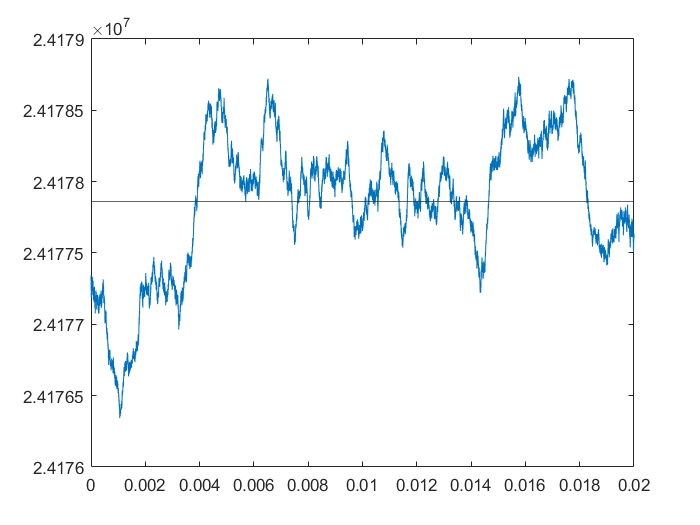

plot(t, f_axion)
yline(f_a)

Qs = logspace(3, 8, 21);
SNRs = zeros(size(Qs));
noise_powers = zeros(size(Qs));
signal_powers = zeros(size(Qs));

f_0 = f_a;
f_0_original = f_a_original;
band_width = 5 * axion_linewidth;
band = [f_0-band_width/2, f_0+band_width/2];

signal = generate_axion_signal(t, f_sampling, f_axion, axion_power_over_Q);
    
RQ = @(Q, df, f_res_o) Q ./ (1 + 4*Q^2 * df.^2 ./ f_res_o.^2 );

parfor j = 1 : length(Qs)
    Q_resonator_original = Qs(j)
    Q_resonator = Q_resonator_original / heterodyning_ratio;
    
    signal_resonated = zeros(size(t));
    noise_resonated = zeros(size(t));
    
    band_width = 2 * f_0 / Q_resonator;
    band = [f_0-band_width/2, f_0+band_width/2];

    state_res = resonator_setup();
    for i = 1 : length(t)
        x = signal(i);
        x = x * sqrt(RQ(Q_resonator_original, f_axion(i)-f_0, f_0_original));
%         [state_res, x] = resonator_step(state_res, x, f_0, Q_resonator, f_sampling);
        signal_resonated(i) = x;
    end

     state_res = resonator_setup();
     for i = 1 : length(t)
         x = noise(i);
         [state_res, y] = resonator_step(state_res, x, f_0, Q_resonator, f_sampling);
         noise_resonated(i) = y;
     end
    signal_powers(j) = bandpower(signal_resonated)%, f_sampling, band)
    noise_powers(j)  = bandpower(noise_resonated)%, f_sampling, band)
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).


bandpower(signal)

ans = 1.4286e-26

signal_powers(2)

ans = 2.5404e-23

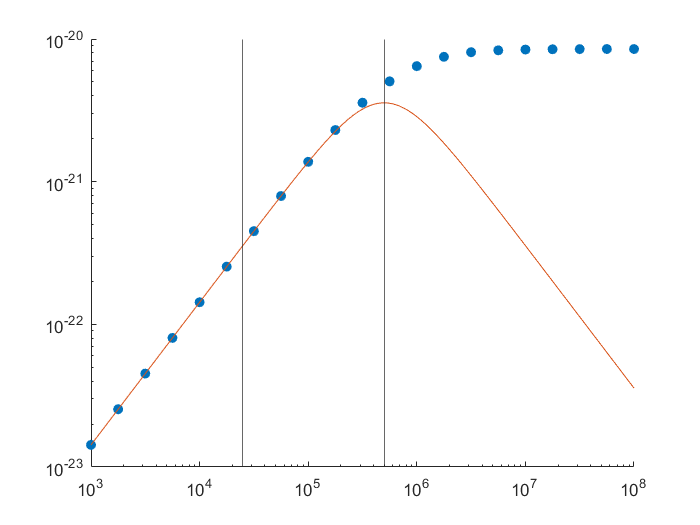

figure
scatter(Qs, signal_powers, 'filled')
set(gca, 'xscale','log', 'yscale','log')
xline(axion_Q/2)
xline(axion_Q/40)
Q_ = logspace(3, 8, 100);
P = axion_power_over_Q * Q_ ./ (1 + 4 * Q_.^2 ./ axion_Q^2);
hold on
plot(Q_, P)

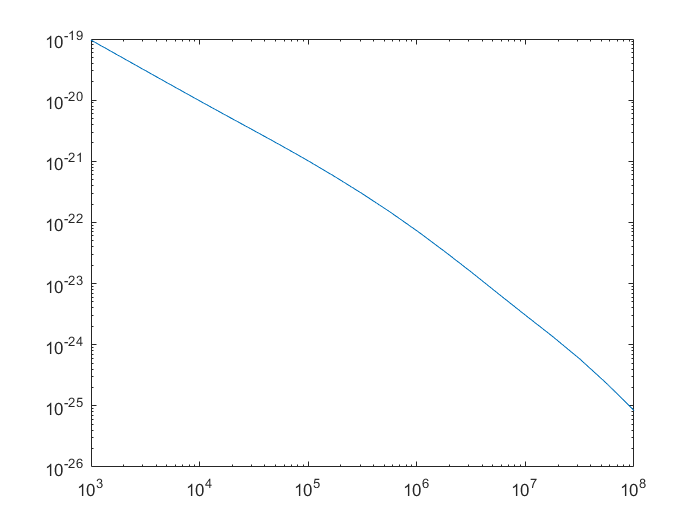

figure
loglog(Qs, noise_powers)

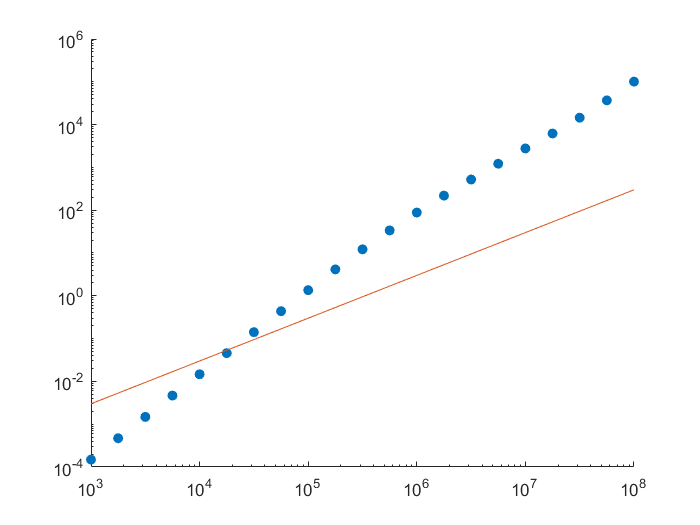

figure
scatter(Qs, signal_powers ./ noise_powers, 'filled')
set(gca, 'xscale','log', 'yscale','log')
hold on
plot(Q_, Q_ * 3e-6)

mean((f_axion - f_0).^2 ./ f_0^2)

ans = 4.0000e-10

axion_linewidth^2 / f_0^2

ans = 4.0000e-10

function ret = alt_RQ(Q, f_ax, f_res)
    width = f_res / Q;
    if abs(f_ax - f_res) < width/2
        ret = Q;
    else
        ret = 0;
    end
end